tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (0.5*s + 10)^4 / 0.001

beta =
 
  0.0625 s^4 + 5 s^3 + 150 s^2 + 2000 s + 10000
  ---------------------------------------------
                      0.001
 
Continuous-time transfer function.




GHsym = [s/alpha, -1/alpha, -1/alpha, 0;
         s/alpha, (alpha - 1/alpha)/s^2, -1/(s^2 * alpha), 1/s^2;
         (1-s/alpha)/beta, -(alpha-1/alpha)/(beta * s^2), 1/(beta*s^2*alpha), -1/(beta*s^2);
         s/(beta*alpha), (1-1/alpha)/beta, -1/(beta*alpha), 0]

GHsym =
 
  From input 1 to output...
                 s
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                 s
   2:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                              2.5e-06 s^2 - 0.0009 s + 0.001
   3:  ----------------------------------------------------------------------------
       0.0001563 s^6 + 0.01875 s^5 + 0.9375 s^4 + 25 s^3 + 375 s^2 + 3000 s + 10000
 
                                         0.001 s
   4:  ----------------------------------------------------------------------------
       0.0001563 s^6 + 0.01875 s^5 + 0.9375 s^4 + 25 s^3 + 375 s^2 + 3000 s + 10000
 
  From input 2 to output...
                 -1
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
       6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s
   2:  ---------------------------------------------
                0.0025 s^4 + 0.1 s^3 + s^2
 
                       -6.25e-09 s^4 - 5e-07 s^3 - 1.5e-05 s^2 - 0.0002 s
   3:  --------



Gss = ss(GHsym, 'minimal')

Gss =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11
   x1      -1.282    -0.4536      6.468    -0.5858    -0.1305     0.1005      5.854     0.8017    -0.8935       0.24     0.8857
   x2       5.013      -12.7     -30.55      3.842      1.675      1.042     -19.87      -1.56     0.7484     -3.958     -2.729
   x3    -0.01581   -0.02882     -22.65      2.224      3.034     -5.763     -41.82      3.166     -2.737     -1.725    -0.5887
   x4    -0.04439     0.3334    -0.2816     -12.35      2.242     -20.75      8.651     -9.556    -0.6549     0.4677     0.5642
   x5      0.1267    -0.9515    -0.9848     -4.544     -2.018     0.7353      1.513     -16.56      4.351      4.208     -1.569
   x6     0.03498    -0.2627    -0.2719    0.05404      8.556     -25.48      5.583       38.5     -14.36     -12.49      4.689
   x7    -0.07158     0.5376     0.5564    -0.1106  -0.005091   -0.05373     -18.34     -

% SS


E1 = [1, 0, 0, 0, 0, 0;
     0, 1, 0, 0, 0, 0;
     0, 0, 1, 0, 0, -tau^2;
     0, 0, 0, 1, -tau^2, 0;
     0, 0, 0, -1/tau^2, 1, 0;
     0, 0, -1/tau^2, 0, 0, 1]

E1 =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0   -0.0025
         0         0         0    1.0000   -0.0025         0
         0         0         0 -400.0000    1.0000         0
         0         0 -400.0000         0         0    1.0000



A1 = [0, 0, 0, 1, 0, 0;
      0, 0, 0, 0, 0, 1;
      0, 1, 0, 0, 0, 2*tau;
      0, 1, 0, 0, 2*tau, 0;
      0, -1/tau^2, 0, 0, -2/tau, 0;
      0, -1/tau^2, 0, 0, 0, -2/tau]

A1 =          0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0    1.0000         0         0         0    0.1000
         0    1.0000         0         0    0.1000         0
         0 -400.0000         0         0  -40.0000         0
         0 -400.0000         0         0         0  -40.0000



B1 = [0, 0, 0, 0;
      0, 0 ,0 ,0;
      0, 1, 1, 0;
      0, 1, 0, 1;
      0, -1/tau^2, 0, -1/tau^2;
      0, -1/tau^2, -1/tau^2, 0]

B1 =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0



L = [0, 1, 0, 0;
     0, 0, 1, 0;
     0, 0, 0, 1;
     -16, -32, -24, -8]

L =      0     1     0     0
     0     0     1     0
     0     0     0     1
   -16   -32   -24    -8



A2 = [L, zeros(4);
      zeros(4), L]

A2 =      0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
   -16   -32   -24    -8     0     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     0     0     0     0   -16   -32   -24    -8



zr4 = zeros(1,4);
B2 = [zr4; zr4; zr4;
      16, 0, 0, 0;
      zr4; zr4; zr4;
      0, 16, 0, 0]

B2 =      0     0     0     0
     0     0     0     0
     0     0     0     0
    16     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0    16     0     0



zr6 = zeros(1,6);

W = [zr6; zr6; zr6;
    -16, 0, zr4;
    zr6; zr6; zr6;
    0, 16, zr4]

W =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
   -16     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0    16     0     0     0     0



Ap = [A1, zeros(6, 8);
     W, A2]

Ap =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0    0.1000         0         0         0         0         0         0         0         0
         0    1.0000         0         0    0.1000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0  -40.0000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0         0  -40.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
        


Bp = [B1;
     B2]

Bp =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   16.0000         0         0         0



E = [E1, zeros(6,8);
    zeros(8,6), eye(8)]

E =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0   -0.0025         0         0         0         0         0         0         0         0
         0         0         0    1.0000   -0.0025         0         0         0         0         0         0         0         0         0
         0         0         0 -400.0000    1.0000         0         0         0         0         0         0         0         0         0
         0         0 -400.0000         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0
         


% this is zero which doesnt seem good
det(E)

ans = 0


% continue on to get C and D
C = [0, 1, zr6, zr6;
     1, 0, zr6, zr6;
     zr6, 1, 0, zr6;
     zr6, zr4, 1, 0, 0, 0]

C =      0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0


D = 0

D = 0

GH = dss(Ap, Bp, C, D, E)

GH =
 
  A = 
          x1    x2    x3    x4    x5    x6    x7    x8    x9   x10   x11   x12   x13   x14
   x1      0     0     0     1     0     0     0     0     0     0     0     0     0     0
   x2      0     0     0     0     0     1     0     0     0     0     0     0     0     0
   x3      0     1     0     0     0   0.1     0     0     0     0     0     0     0     0
   x4      0     1     0     0   0.1     0     0     0     0     0     0     0     0     0
   x5      0  -400     0     0   -40     0     0     0     0     0     0     0     0     0
   x6      0  -400     0     0     0   -40     0     0     0     0     0     0     0     0
   x7      0     0     0     0     0     0     0     1     0     0     0     0     0     0
   x8      0     0     0     0     0     0     0     0     1     0     0     0     0     0
   x9      0     0     0     0     0     0     0     0     0     1     0     0     0     0
   x10   -16     0     0     0     0     0   -16   -32   -24    -8     0    

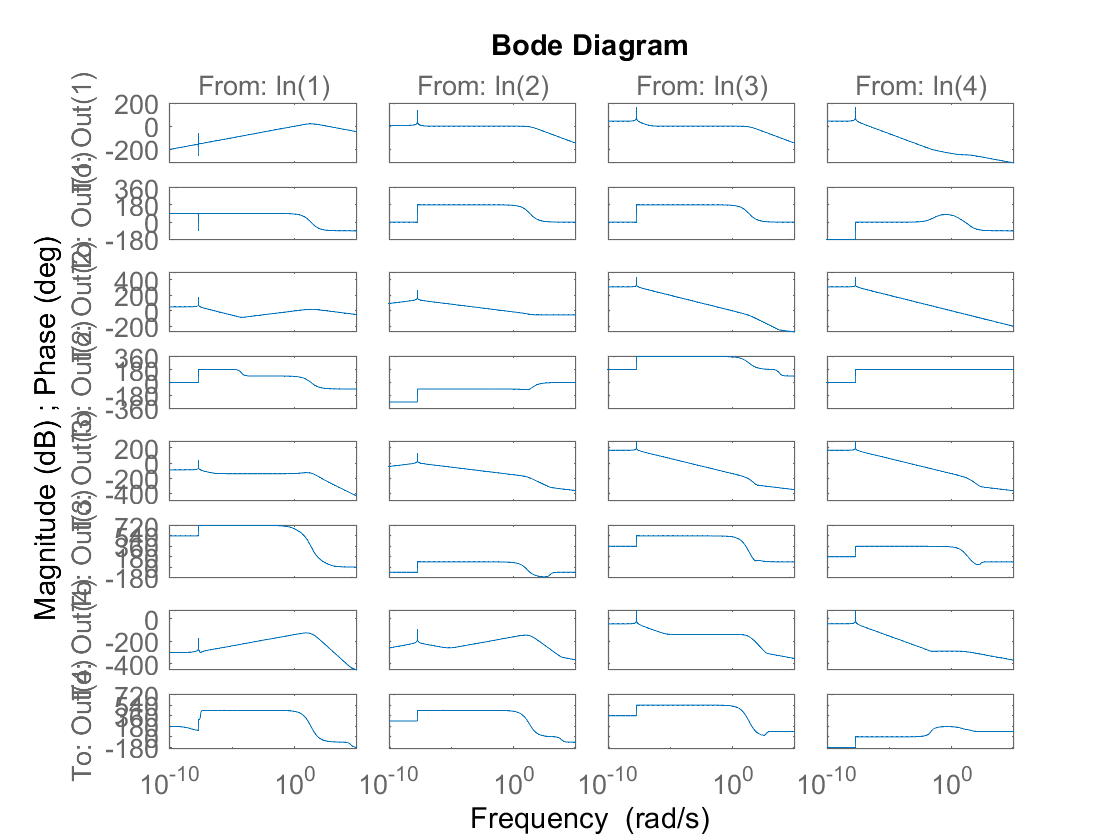


bode(Gss)


A = Gss.A

A =    -1.2823   -0.4536    6.4680   -0.5858   -0.1305    0.1005    5.8536    0.8017   -0.8935    0.2400    0.8857   -1.2841   -5.4901   -1.6476
    5.0134  -12.7044  -30.5450    3.8418    1.6747    1.0422  -19.8743   -1.5600    0.7484   -3.9575   -2.7287   -0.0858   -0.2860   -0.0229
   -0.0158   -0.0288  -22.6493    2.2235    3.0336   -5.7627  -41.8215    3.1660   -2.7370   -1.7254   -0.5887   -0.1878   -0.1821   -0.5652
   -0.0444    0.3334   -0.2816  -12.3524    2.2418  -20.7550    8.6506   -9.5563   -0.6549    0.4677    0.5642   -0.4635    0.6250    0.1594
    0.1267   -0.9515   -0.9848   -4.5440   -2.0178    0.7353    1.5128  -16.5553    4.3508    4.2085   -1.5687   -0.4919   -2.3014   -0.2599
    0.0350   -0.2627   -0.2719    0.0540    8.5563  -25.4802    5.5829   38.4963  -14.3598  -12.4888    4.6888    0.1517    4.0648   -0.0190
   -0.0716    0.5376    0.5564   -0.1106   -0.0051   -0.0537  -18.3402   -3.6332    1.0710    0.9451   -0.7352    0.0256   -0.1922    0.0718
   -0.024

B = Gss.B(:, 1:2);
C = Gss.C(3:4, :);
D = Gss.D(3:4, 1:2);

gamma = 0.1; % for example

n = size(A,1);
m = size(B,2);
p = size(C,1);

% LMIs
setlmis([]);

P = lmivar(1,[n 1]);

lmi1 = newlmi;

% Schur component
%   [ A^T P + P A,   P B,        C^T
%     B^T P,         -gamma^2 I, D^T
%     C,             D,          -gamma^2 I ] < 0

% 'lmiterm([lmi row col X], A, B, flag)' means "place A*X*B into (row,col)
% block

% (1,1) A^T P + P A
lmiterm([lmi1 1 1 P], A', 1, 's');  
% The 's' flag makes it add the symmetric term P*A.

% (2,2) block: -gamma^2 I (dimension m×m)
lmiterm([lmi1 2 2 0], -gamma^2*eye(m));

% (3,3) block: -gamma^2 I (dimension p×p)
lmiterm([lmi1 3 3 0], -gamma^2*eye(p));

% (1,2) block: P B
lmiterm([lmi1 1 2 P], 1, B);  

% (2,1) block: B^T P
lmiterm([lmi1 2 1 P], B', 1);

% (1,3) block: C^T
lmiterm([lmi1 1 3 0], C');

% (3,1) block: C
lmiterm([lmi1 3 1 0], C);

% (2,3) block: D^T
lmiterm([lmi1 2 3 0], D');

% (3,2) block is the transpose: D
lmiterm([lmi1 3 2 0], D);

% need another LMI
lmi2 = newlmi;
% P > 0
lmiterm([lmi2 1 1 P], 1, 1);
% definition of LMIs should be done

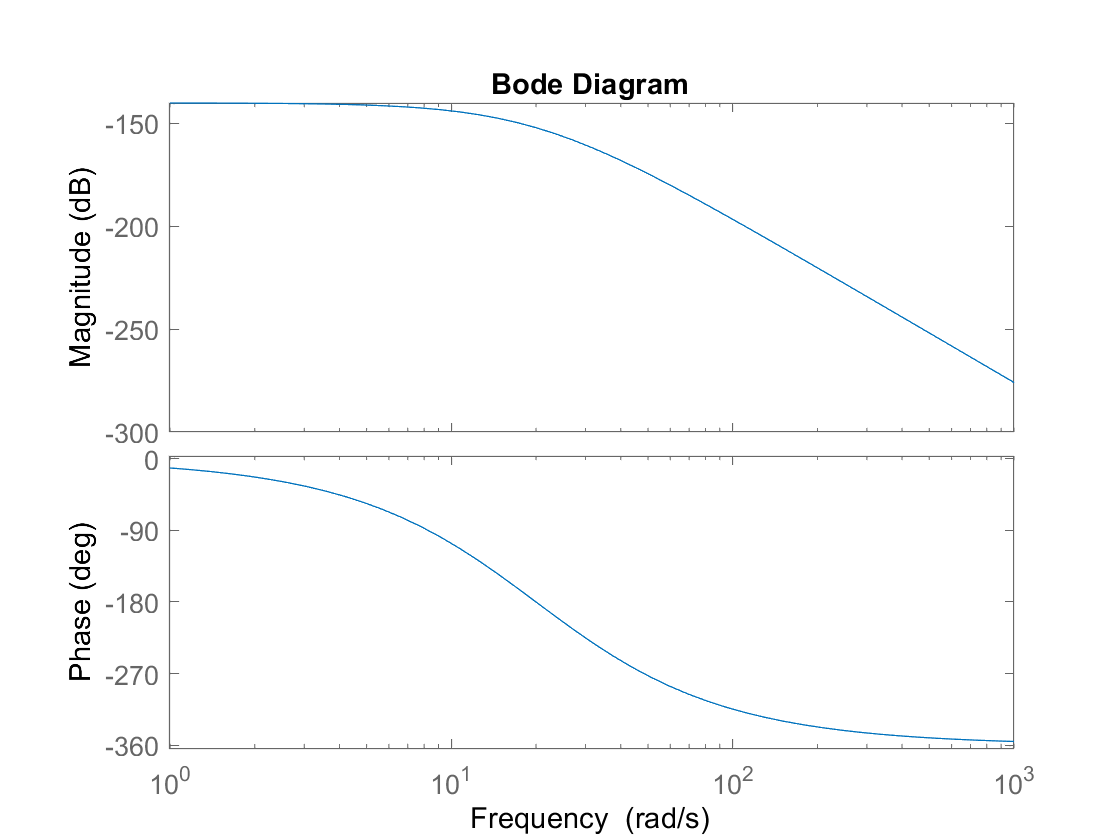

bode(1/beta);


lmisys = getlmis;

options = [0 0 0 0 1];
[tmin, xfeas] = feasp(lmisys, options);

if tmin < 0
    disp('A feasible P was found => ||G||_inf < gamma');
    % calc P matrix
    Psol = dec2mat(lmisys, xfeas, P);
    disp('P = '), disp(Psol)
else
    disp('No feasible solution => cannot conclude ||G||_inf < gamma');
end

No feasible solution => cannot conclude ||G||_inf < gamma
